`1. 分别用脉冲响应不变法和双线性变换法设计一个巴特沃斯低通IIR数字滤波器，设计指标参数为：在通带内频率低于0.2`p`时，最大衰减小于1dB，在阻带内[0.3`p`，`p`]频率区间上，最小衰减大于15dB。`

`观察并画出所设计数字滤波器的幅频特性曲线和相频特性曲线，记录带宽和衰减量，检查是否满足要求。比较这两种方法的优缺点。`

`(1) 脉冲响应不变法设计`

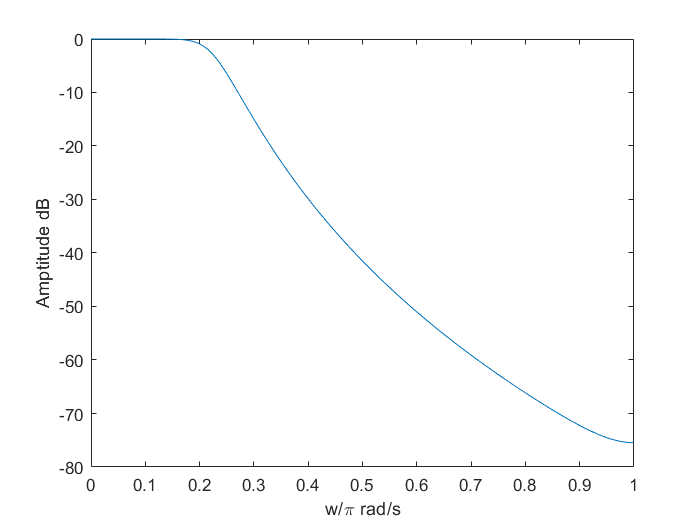

%=======巴特沃斯滤波器设计(脉冲响应不变法)=======
T = 1;
clf;
wp = 0.2*pi/T;ws = 0.3*pi/T;% 确定模拟滤波器指标
rp = 1;  rs = 15;
[N, wc] = buttord(wp, ws, rp, rs, 's');  % 计算模拟滤波器阶数N与3dB截止频率
[B, A] = butter(N, wc,'s'); % 获得系统函数参数

[Bz, Az] = impinvar(B, A, 1/T); % 脉冲响应不变法转换为数字滤波器
%=======绘制滤波器曲线=======
[h,w] = freqz(Bz, Az,[0:0.01:pi]); % 绘制图
A = 20*log10(abs(h));
plot(w/pi, A);
xlabel("w/\pi rad/s")
ylabel("Amptitude dB");

hold on;

%=======绘制关键点衰减值=======
hfig = fvtool(Bz, Az)

hfig =   Figure (filtervisualizationtool) - 属性:

      Number: 8
        Name: 'Magnitude Response (dB)'
       Color: [0.9400 0.9400 0.9400]
    Position: [1 1 772.8000 662.4000]
       Units: 'pixels'

  使用 get 显示所有属性


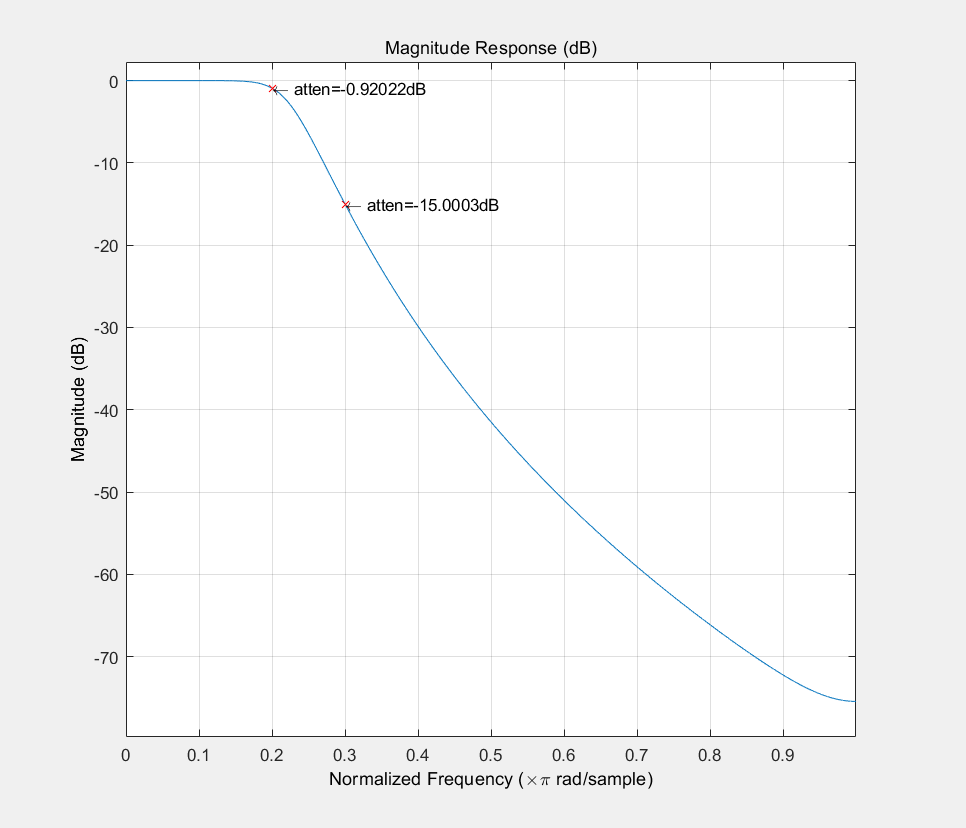

hold on;
[h,w] = freqz(Bz, Az,[0.2*pi,0.3*pi]); % 绘制图
A = 20*log10(abs(h));
plot(w/pi, A, 'rx');
text(w(1)/pi, A(1),['\leftarrow atten=' num2str(A(1)) 'dB']);  % 绘制0.2p 处衰减值
text(w(2)/pi, A(2),['\leftarrow atten=' num2str(A(2)) 'dB']); % 绘制0.3p 处衰减值

衰减量符合要求

`(2) 双线性变换法设计`

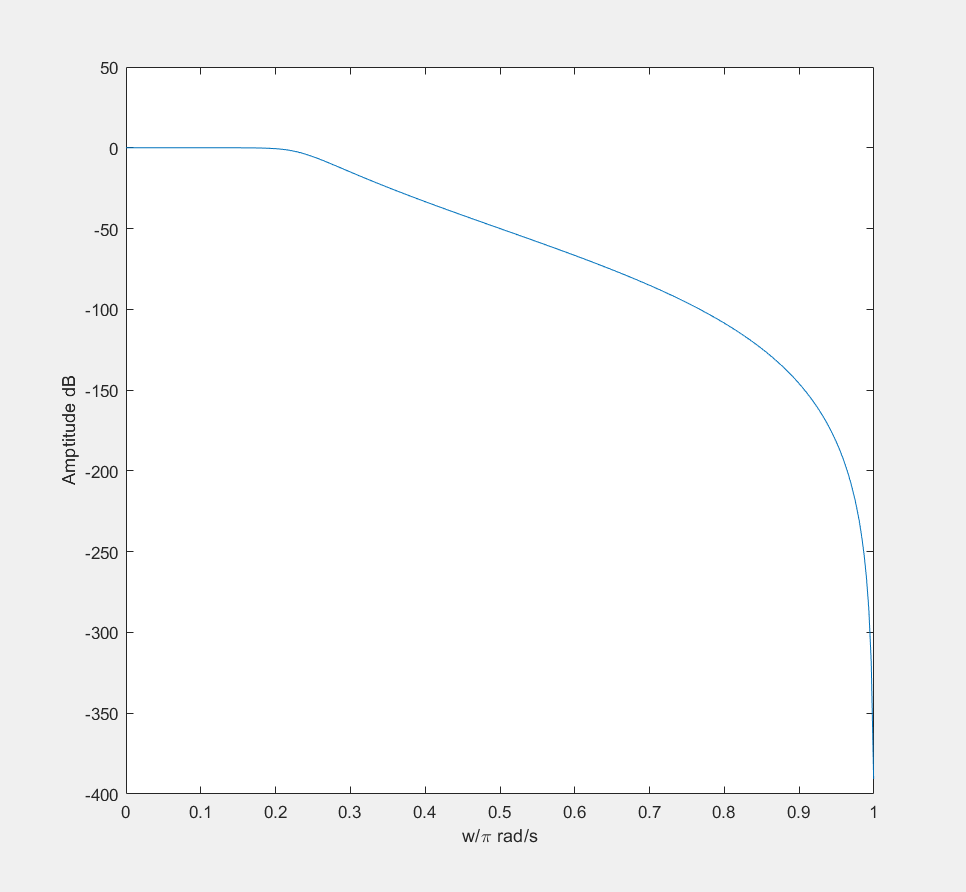

%========数字滤波器设计=========
clf;
rp = 1;  rs = 15;
wsz = 0.3;  wpz = 0.2;   % 归一化Π参数

[N, wc] = buttord(wpz, wsz, rp,rs);
[Bz, Az] = butter(N, wc,'low');
% fvtool(B,A)

%=======绘制滤波器曲线=======
[h,w] = freqz(Bz, Az,[0:0.01:pi]); % 绘制图
A = 20*log10(abs(h));
plot(w/pi, A);
xlabel("w/\pi rad/s")
ylabel("Amptitude dB");



%=======绘制关键点衰减值=======
addfilter(hfig,Bz,Az);

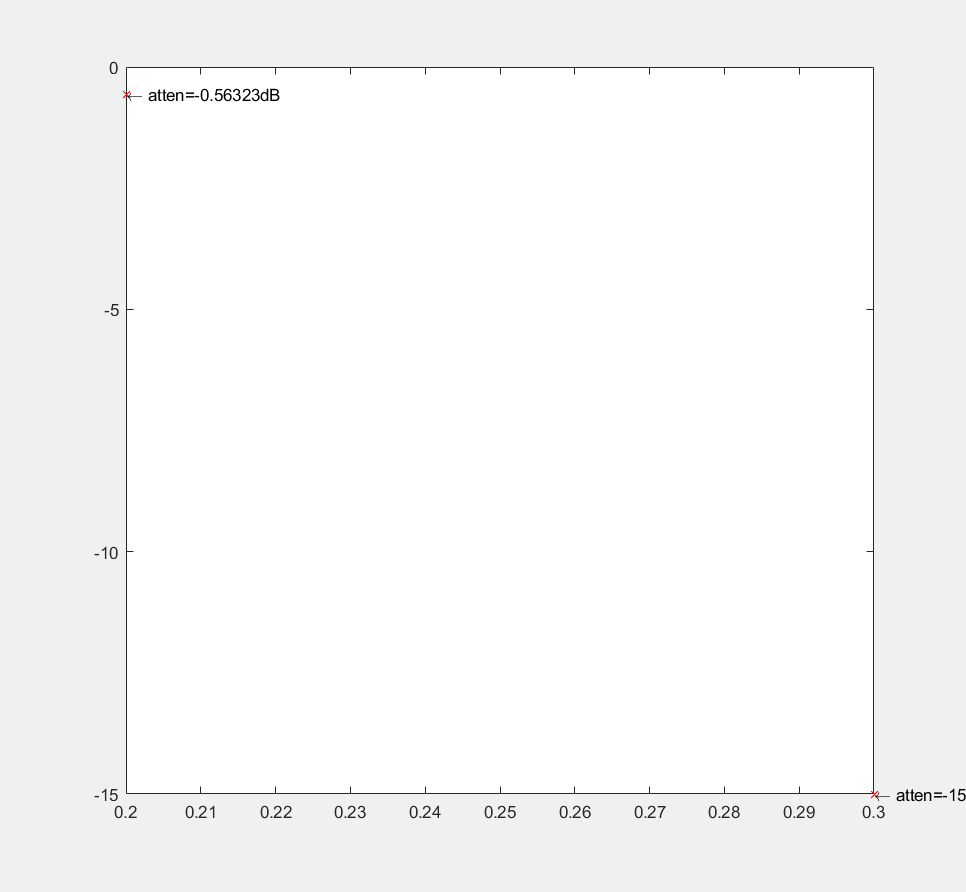


[h,w] = freqz(Bz, Az,[0.2*pi,0.3*pi]); % 绘制图
A = 20*log10(abs(h));
plot(w/pi, A, 'rx');
text(w(1)/pi, A(1),['\leftarrow atten=' num2str(A(1)) 'dB']);  % 绘制0.2p 处衰减值
text(w(2)/pi, A(2),['\leftarrow atten=' num2str(A(2)) 'dB']); % 绘制0.3p 处衰减值

可以看到衰减量符合要求

`2. 用双线性变换法设计一个切比雪夫高通IIR数字滤波器，设计指标参数为：在通带内频率高于0.3KHz, 最大衰减小于1dB，在阻带内频率低于0.2 KHz，最小衰减大于20dB，T=1ms。 画出所设计数字滤波器的幅频特性曲线和相频特性曲线，观察其通带损耗和阻带衰减是否满足要求。`

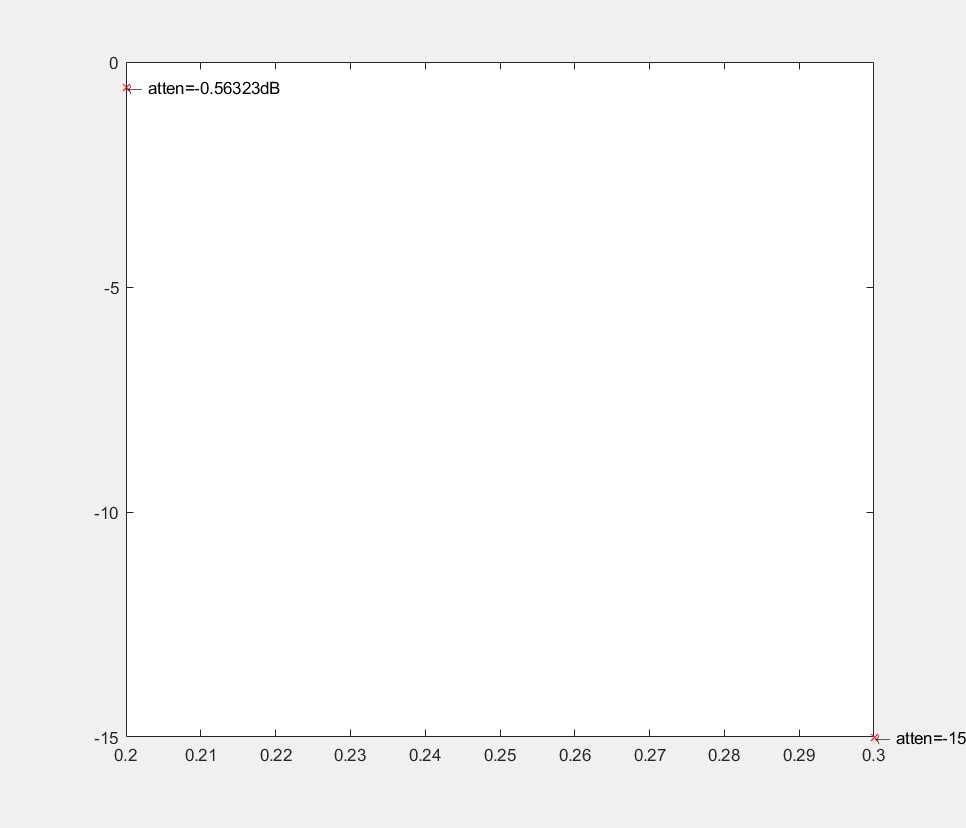

hold off;

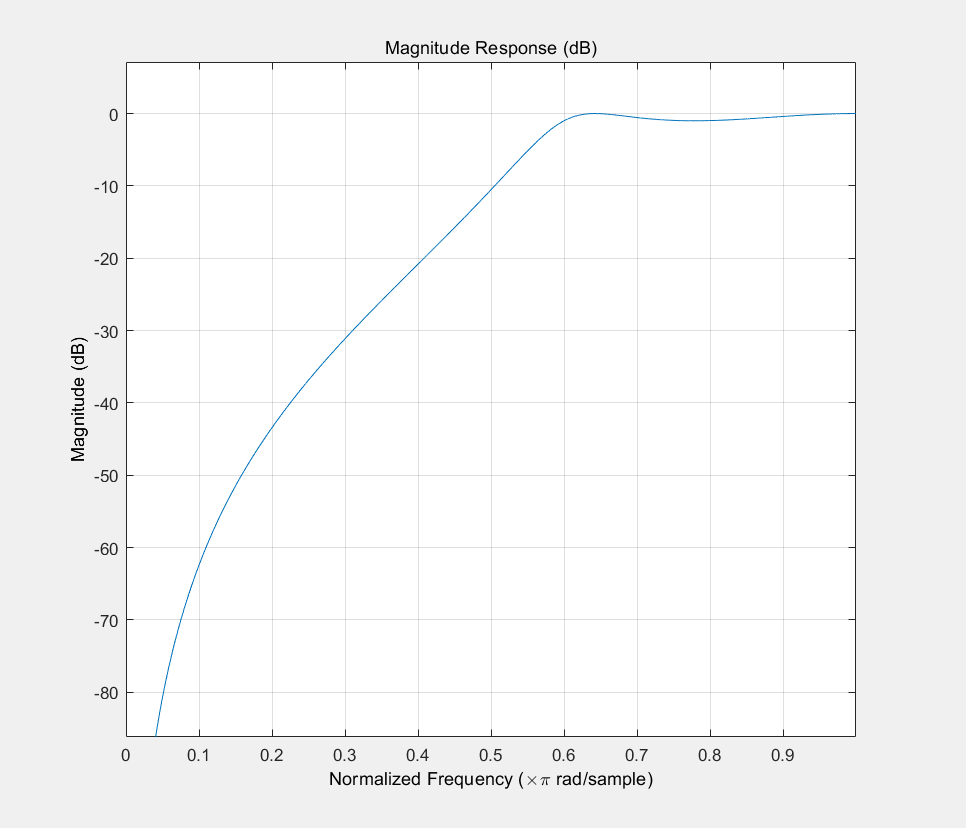

fp = 300;  fs = 200; Fs = 1000;
rp = 1; rs = 20;
wpz = 2*fp/Fs; wsz = 2*fs/Fs;

[N1 , wp1] = cheb1ord(wpz,wsz, rp,rs);
[Bz1, Az2] = cheby1(N1, rp, wp1,'high');

fvtool(Bz1, Az2);

符合要求

`3. 人体心电图信号在测量过程中往往受到工业高频干扰，所以必须经过低通滤波处理后，才能作为判断心脏功能的有用信息。下面给出一实际心电图信号采样序列样本x(n)，其中存在高频干扰。 用1所计的滤波器对心电图信号采样序列x(n)进行仿真滤波处理，画出处理前后的信号波形`

xn = [-4, -2, 0, -4,-6, -4,-2,-4,-6,-6,-4,-4-6-6,-2,6,12,8,0,-16,-38,-60,84,-90,-66,-32,-4,-2,-4,-8,12,12,10,6,6,6,4,0,0,0, 0,0,-2,-4,0,0,0,-2,-2,0,0,-2,-2,-2,-2,0]

xn =     -4    -2     0    -4    -6    -4    -2    -4    -6    -6    -4   -16    -2     6    12     8     0   -16   -38   -60    84   -90   -66   -32    -4    -2    -4    -8    12    12    10     6     6     6     4     0     0     0     0     0    -2    -4     0     0     0    -2    -2     0     0    -2


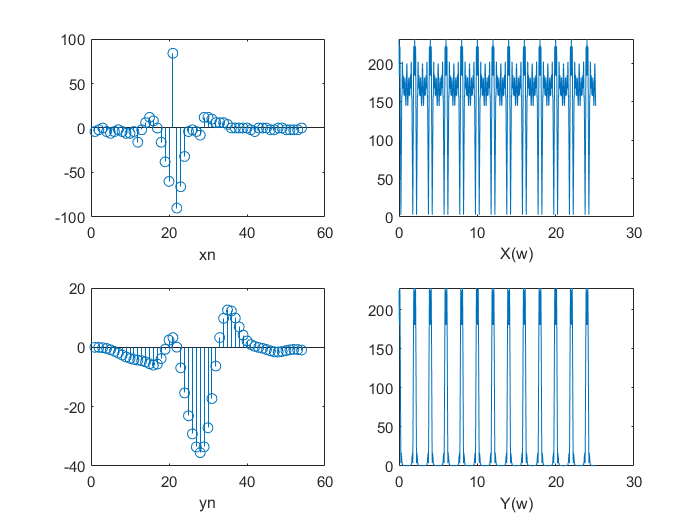

subplot(2,2,1);
stem(xn);
xlabel("xn");

subplot(2,2,2);
wx = [0:0.01:8*pi];
plot(wx,dtft(xn, wx));
% 放不同
xlabel("X(w)");

subplot(2,2,3);
yn = filter(Bz, Az, xn);
stem(yn)

xlabel("yn");

subplot(2,2,4);
plot(wx,dtft(yn, wx));
xlabel("Y(w)");